device = serialport("COM4",115200,"Timeout",5)

device =   Serialport with properties:

                 Port: "COM4"
             BaudRate: 115200
                  Tag: ""
    NumBytesAvailable: 0

  Show all properties, functions


configureTerminator(device,"CR")

readString = "";
impedanceSpectreAtPeakIndices = [];
while (1)
    readString = readline(device);
    impedanceSpectreAtPeakIndices = [impedanceSpectreAtPeakIndices; str2double(split(readString,","))'];
end

Error using split (line 9)
First argument must be text.

clear("device")
S = serialportfind


S =

     []



delete(S)

% Change the folder name!
% Change the DC adder OPAMP pin:
%   -Imp signal for: LRs, CRp
%   -OPA signal for: LRp, CRs

%filename = "LRs.csv"
%filename = "LRp1.csv"
% filename = "CRs1.csv"
filename = "CRp.csv"

filename = "CRp.csv"


writematrix(impedanceSpectreAtPeakIndices,filename)
clear("impedanceSpectreAtPeakIndices")

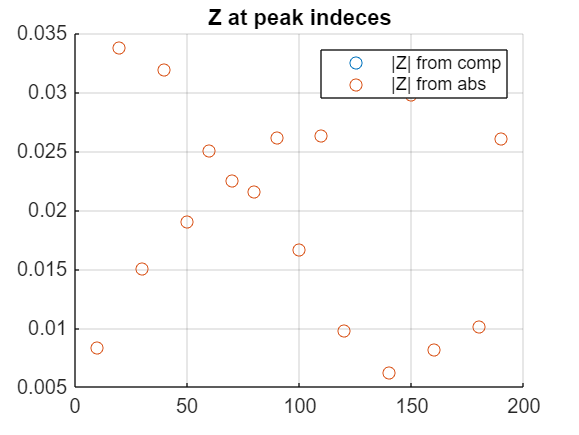


impedanceSpectreAtPeakIndicesRead = readtable(filename);

% Measured complex plotting
FFT_BUFFER_SIZE = 1024;
T = impedanceSpectreAtPeakIndicesRead{:,:};
f = T(:,1);
Z_c = T(:,2)+1i*T(:,3);
Z_a = T(:,4);
Z_c_a = abs(Z_c)*2/FFT_BUFFER_SIZE;
Z_fi = angle(Z_c);

figure()
scatter(f,Z_c_a);
hold on
scatter(f,Z_a);
hold off
title('Z at peak indeces')
legend('|Z| from comp','|Z| from abs')
grid on